In this script we need to find the IC that make the pendulum hit the wall in spesific condition


fun =@My_DoublePendulum; %insert function to be solved   
% sol  = fsolve(@FindBothInitials,[2.2,0.5]);
% ShowMe(sol)

1 Find an initial state so that the pendulum’s second link will collide

flat with the wall.

sol = My_Secant(@FindBothInitials,[0 0.2],1e5,1e-8); % section a solution with secant method
disp(sol)

    1.0317    0.3976



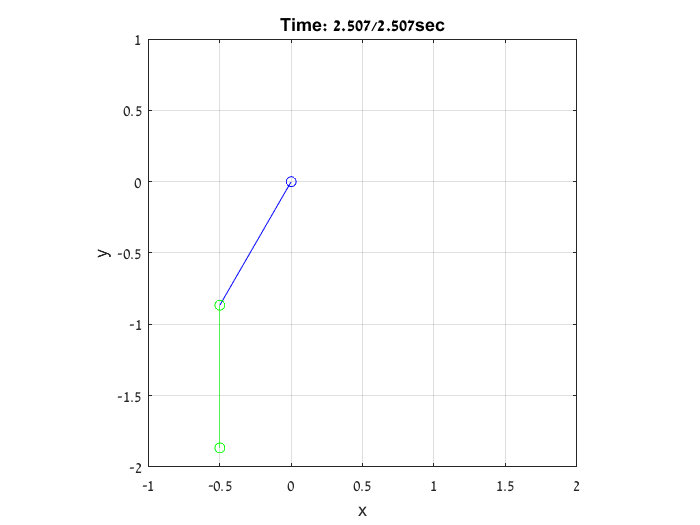

ShowMe(sol)

2 Find an initial state [1, 𝜃0𝑡𝑜𝑝 , 0,0] that will cause the top point of the second link

to hit the wall

sol  = fzero(@(tk) FindInitials(tk,'top'),0.2); %section b solution .
disp(sol)

    0.2000



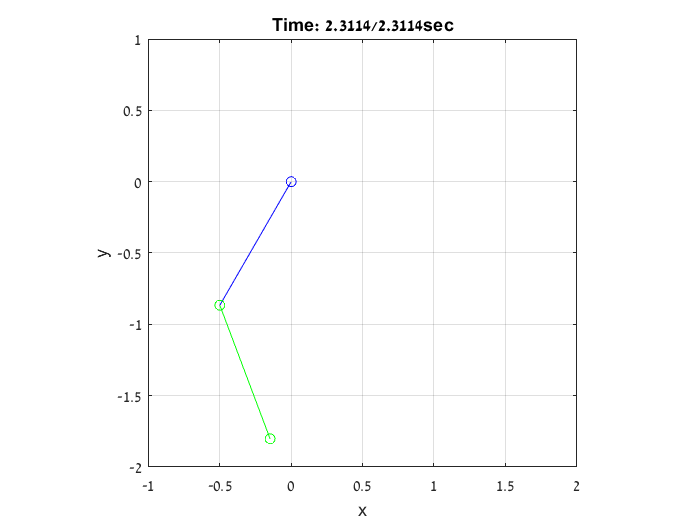

ShowMe([1 sol])

3. Find an initial state [1, 𝜃0𝑏𝑜𝑡 , 0,0] that will cause the bottom point of the second link to hit the wall

sol= fzero(@(tk) FindInitials(tk,'bottom'),1); %section c solution
disp(sol)

     1



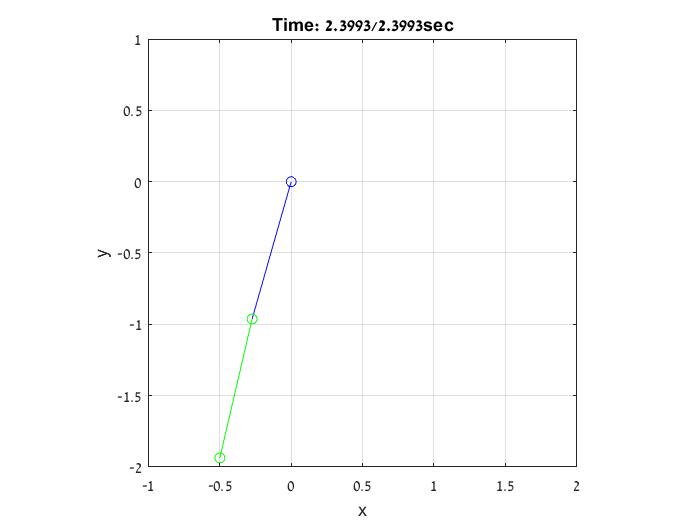

ShowMe([1 sol])

function err = FindBothInitials(tk)    
% this function detrmaine the problem to find both initial condition.
    y0 = [tk(1) tk(2) 0 0] ; % take 2 geusses at the same time
    yb1 = [-pi/6 ,0]; yb2 = [7*pi/6 ,0]; % considere 2 solution (from Q4 - a)
    h = 0.1; % initial step size
    [~,yS] = MY_RK4_event(@(t,y) My_DoublePendulum(t,y),h,[0 20],y0); % solve with th initial until event occur
    sol_1 = yS(end,1:2)-yb1; % check the error to solution 1
    sol_2 = yS(end,1:2)-yb2; % check the error to solution 2
    % consider only the minimum error (calculte by norm infinty)
    if norm(sol_1,'inf') < norm(sol_2,'inf') 
        err = sol_1;
    else
        err = sol_2;
    end
end

function err = FindInitials(tk,loc)    
% This function detrmaine the problem to find initial condition for theta 2, it sparated to cased by parameter 'loc'.    
    y0 = [1 tk 0 0] ;  % take initial geusses
    yb1 = [-pi/6 ,0]; yb2 = [7*pi/6 ,0]; % considere 2 solution (from Q4 - a)
    h = 0.1; l1 =1; l2 = 1; % set parameters
    [~,yS] = MY_RK4_event(@(t,y) My_DoublePendulum(t,y),h,[0 20],y0); % solve with th initial until event occur
    if strcmp(loc,'top') % check only if the top link collide
        err = min([abs(yS(end,1)-yb1(1)),abs(yS(end,1)-yb2(1))]); % define the min distance to one of the solution
        if err < 1e-8 % in order to use fzero function we have to cross zero.
            err = 0;
        end
    else
        err = l1*sin(yS(end,1))+l2*sin(yS(end,2))+0.5; % link's bootom position (BTW allways positive with the event function)
        if abs(err) < 1e-8
            err = 0;
        end
    end
end
